# FUcking finals

## ANOVA

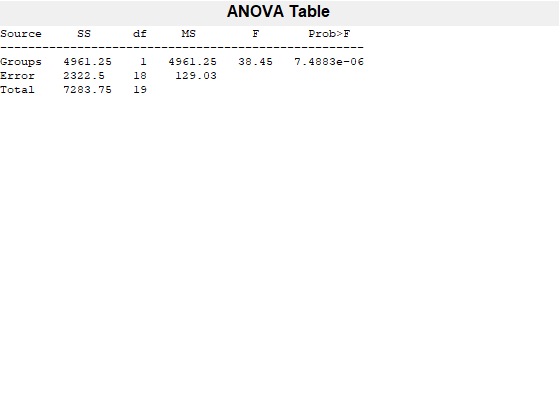

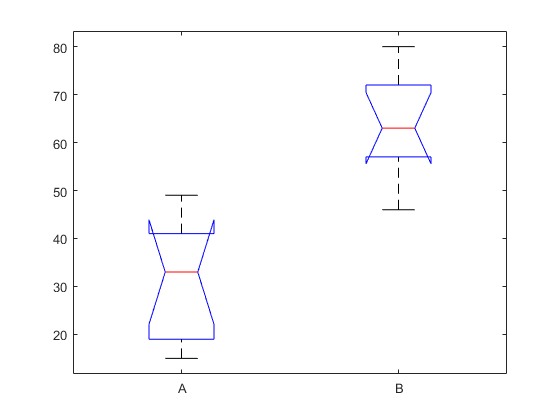

I = 4; % population/Group
y1 = [27 45 41 19 35 39 19 49 15 31];
y2 = [57 64 80 46 62 72 52 77 57 68];
% y3 = [134 139 135 138];
% y4 = [149 150];

y_cell = {y1,y2};
I = length(y_cell); % population/Group
y = [];
J = [];
g = {};
for i = 1:I
    y = [y y_cell{i}];
    Ji = length(y_cell{i});
    J = [J Ji];
    
    if i ~= 1
        s = e+1;
    else
        s = 1;
    end
    e = s+J(i)-1;
    for k = s:e
        g{k} = char(i+64);
    end
end

n = length(y);
anova1(y,g);

## RxC table

- Homogeneity:  p1 = p2 = ... = pi

- Independence: pij = pi*pj

o_tb = [252 107 43;139 81 40]; %% row: outcome; col: treatments/groups;
n = sum(o_tb,'all');
nr = sum(o_tb,1);
nc = sum(o_tb,2);
[r,c] = size(o_tb);

df = (r-1)*(c-1)

df = 2

alpha = 0.05;
chi2inv(1-alpha,df)

ans = 5.9915


e_tb = zeros(r,c);
for i = 1:r
    for j = 1:c
        e_tb(i,j) = nr(j)*nc(i)/n;
    end
end
e_tb

e_tb =   237.4350  114.1631   50.4018
  153.5650   73.8369   32.5982


chi2val = sum((o_tb-e_tb).^2./(e_tb),'all')

chi2val = 6.1869